data = importdata('./data_problem4/data1/data1.mat');
[mu,U,Y,~] = PCA_via_SVD(data, 10);
%imshow(reshape(data(:,1),48,42));
imshow(reshape(mu,[48,42]),[]);
count = 0;
for i = [1,2,3,10]
    count = count + 1;
    U1 = reshape(U(:,i),[48,42]);
    %U1 = normalize(U1,'range');
    subplot(1,4,count);imshow(U1,[],'border','tight','initialmagnification','fit');
end

clf;
all_data = importdata('./data_problem4/all_data.mat');
train_data = all_data.data_train;
[mu,U,Y,sigma] = PCA_via_SVD(train_data, 10);
%imshow(reshape(data(:,1),48,42));
imshow(reshape(mu,48,42),[]);
count = 0;
for i = [1,2,3,10]
    count = count + 1;
    U1 = reshape(U(:,i),48,42);
    %U1 = normalize(U1,'range');
    subplot(1,4, count);imshow(U1,[]);
end

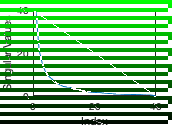

%Project
clf;
plot(diag(sigma));xlabel('Index');ylabel('Singular Values');

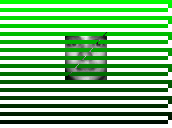

test_data = all_data.data_test;
d = 2;
[mu,U,Y,sigma] = PCA_via_SVD(train_data, d);
imshow(reshape(mu,[48,42]),[]);

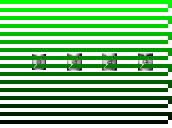

U_d = U(:,1:d);

[m,n] = size(test_data);
Y_test = U_d' * (test_data - mu * ones([1,n]));
proj_X_test = mu * ones([1,n]) + U_d * Y_test;
clf;
for i = 1:4
    subplot(1,4,i);
    %imshow(reshape(test_data(:,i),48,42));
    %proj_X_test(:,i) = normalize(proj_X_test(:,i),'range');
    imshow(reshape(proj_X_test(:,1 + 5 * (i - 1)),[48,42]),[]);
end

%error
train_data = all_data.data_train;
test_data = all_data.data_test;
error = [];
for d = 2:8
    % Find the projected image of trainning set
    [mu,U,Y,sigma] = PCA_via_SVD(train_data, d);
    U_d = U(:,1:d);
    % Find the projected image of test set
    [m,n] = size(test_data);
    Y_test = U_d' * (test_data - mu * ones([1,n]));
    % Here we compute the distance
    prediction = [];
    count = 0;
    for i = 1:20
        min_dist = 100000;
        pred = 0;
        for j = 1:40
            dist = norm(Y_test(:,i) - Y(:,j), 2);
            if dist < min_dist
                min_dist = dist;
                pred = all_data.Y_label_train(j);
            end
        end
        if pred == all_data.Y_label_test(i)
            count = count + 1;
        end
    end
    error = [error, (20 - count)/20];
end